# Derivada direccional

La derivada direccional de una función $f(x,y,z)$ en la dirección de un vector unitario $u = (u_1, u_2, u_3)$ se define como:


$$D_uf = \nabla f \cdot u = \frac{\partial f}{\partial x}u_1 + \frac{\partial f}{\partial y}u_2 + \frac{\partial f}{\partial z}u_3$$


donde $\nabla f$ es el gradiente de $f$ y $u=(u_1,u_2,u_3)$ un vector unitario que determina la dirección del cambio sobre la función.

Las derivadas parciales de $f$ para cada variable se pueden obtener usando diferencias finitas centradas:


$$\frac{\partial f}{\partial x}\approx\frac{f(x+h,y,z)-f(x-h,y,z)}{2h}$$



$$\frac{\partial f}{\partial y}\approx\frac{f(x,y+h,z)-f(x,y-h,z)}{2h}$$



$$\frac{\partial f}{\partial z}\approx\frac{f(x,y,z+h)-f(x,y,z-h)}{2h}$$


y donde el valor del tamaño de paso $h$ es arbitrario.

%FUNCIÓN AL FINAL

## Ejemplo 1

Calcular la tasa de cambio de la temperatura en un punto del manto terrestre en dirección a un punto de posible pluma mantélica. Usa un model térmico simplificado para la temperatura en °C:


$$T(x,y,z)=20-0.5z+0.01z^2+0.1xy$$


% Código principal

% Parámetros iniciales
punto = [100, 100, -500];
direccion = [30, 40, -10];

% Calcular derivada direccional
dd = derivada_direccional(@temperatura_manto, punto, direccion);
fprintf('Derivada direccional de la temperatura: %.2f °C/km\n', dd);


Derivada direccional de la temperatura: 15.79 °C/km


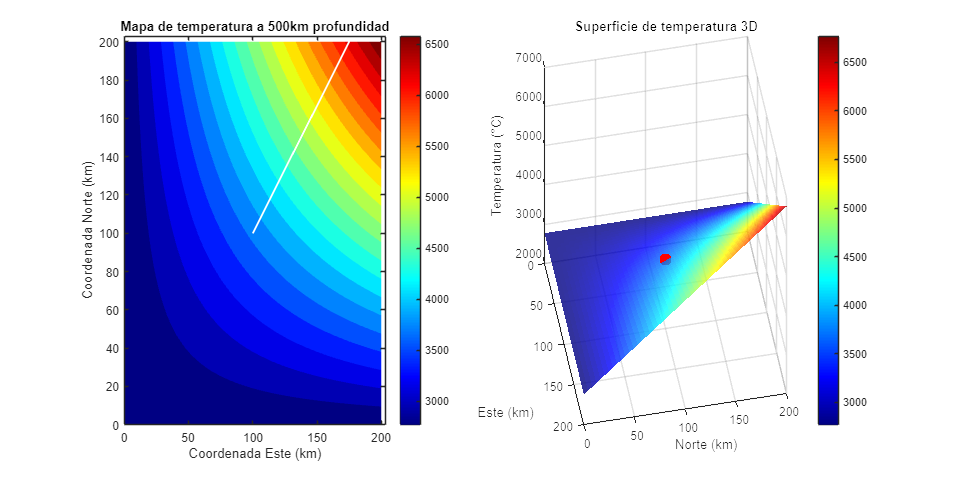

% Crear malla de puntos
x_vals = linspace(0, 200, 50);
y_vals = linspace(0, 200, 50);
[X, Y] = meshgrid(x_vals, y_vals);
Z = -500 * ones(size(X));  % Plano a z=-500

% Calcular temperatura
T = temperatura_manto(X, Y, Z);

% Crear figura
figure('Position', [100, 100, 1200, 600]);

% Gráfica 2D
subplot(1,2,1);
contourf(X, Y, T, 20, 'LineColor', 'none');
colormap jet;
colorbar;
title('Mapa de temperatura a 500km profundidad');
xlabel('Coordenada Este (km)');
ylabel('Coordenada Norte (km)');
hold on;
quiver(punto(1), punto(2), direccion(1) * 10, direccion(2) * 10, 'Color', 'white', 'LineWidth', 1.5);
hold off;

% Gráfica 3D
subplot(1,2,2);
surf(X, Y, T, 'EdgeColor', 'none', 'FaceAlpha', 0.8);
colormap jet;
colorbar;
title('Superficie de temperatura 3D');
xlabel('Este (km)');
ylabel('Norte (km)');
zlabel('Temperatura (°C)');
hold on;
scatter3(punto(1), punto(2), temperatura_manto(punto(1), punto(2), punto(3)), ...
    'filled', 'MarkerFaceColor', 'r', 'SizeData', 100);
hold off;

subplot(1,2,1)
xlim([0 203])
ylim([0 203])
subplot(1,2,2)
view([79 40])


% Ajustar diseño
set(gcf, 'Color', 'w');

% Funciones al final del archivo


### Ejercicio 1

Usando el gradiente de la función analítica:

- Calcula el valor la derivada direccional.

- Calcula el tamaño de paso h necesario para que la aproximación de la derivada direccional tenga un error de $\pm 1\degree C/m$ con respecto al valor analítico.

## Ejemplo 2

Calcular la tasa de cambio de la densidad de plasma en la magnetosfera terrestre en dirección al viento solar. Utilizando el modelo de densidad de plasma:


$$n(x,y,z)=10^6\cdot e^{-r/7}\cdot (2+\text{sen}\theta)$$


donde $n$ es el número de partículas por unidad de volumen en $cm^3$ y la distancia $r=\sqrt{x^2+y^2+z^2}$ y $\theta=\left(\frac{\sqrt{y^2+z^2}}{x}\right)$.

% Código principal

% Parámetros iniciales
punto = [10, 0, 0];  % Punto en la magnetosfera (10 radios terrestres)
direccion = [0.9, 0.1, -0.05];  % Dirección del viento solar

% Calcular derivada direccional
dd_plasma = derivada_direccional(@densidad_plasma, punto, direccion);
fprintf('Derivada direccional: %.2e partículas/cm³ por RT\n', dd_plasma);

Derivada direccional: -6.79e+04 partículas/cm³ por RT


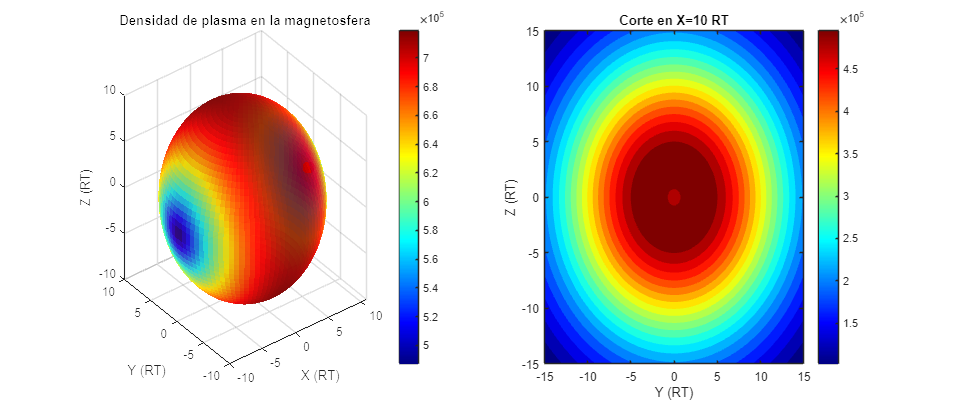


% Visualización
theta = linspace(0, 2*pi, 100);
phi = linspace(0, pi, 50);
[THETA, PHI] = meshgrid(theta, phi);
R = 10;  % Radio de visualización

% Convertir a coordenadas cartesianas
X = R * sin(PHI) .* cos(THETA);
Y = R * sin(PHI) .* sin(THETA);
Z = R * cos(PHI);

% Calcular densidad en la superficie
D = densidad_plasma(X, Y, Z);

% Crear figura
figure('Position', [100, 100, 1400, 600]);

% Gráfica 3D
subplot(1, 2, 1);
surf(X, Y, Z, D, 'EdgeColor', 'none', 'FaceAlpha', 0.8);
colormap jet;
colorbar;
hold on;
scatter3(punto(1), punto(2), punto(3), 100, 'r', 'filled');
quiver3(punto(1), punto(2), punto(3), direccion(1), direccion(2), direccion(3), ...
    'Color', 'w', 'LineWidth', 1.5, 'MaxHeadSize', 1);
hold off;
title('Densidad de plasma en la magnetosfera');
xlabel('X (RT)');
ylabel('Y (RT)');
zlabel('Z (RT)');

% Corte 2D
subplot(1, 2, 2);
y_vals = linspace(-15, 15, 100);
z_vals = linspace(-15, 15, 100);
[Y, Z] = meshgrid(y_vals, z_vals);
X = 10 * ones(size(Y));
D_corte = densidad_plasma(X, Y, Z);

contourf(Y, Z, D_corte, 20, 'LineColor', 'none');
colormap jet;
colorbar;
title('Corte en X=10 RT');
xlabel('Y (RT)');
ylabel('Z (RT)');


% Ajustar diseño
set(gcf, 'Color', 'w');

% Funciones al final del archivo



### Ejercicio 2

Usando el gradiente de la función analítica:

- Calcula el valor de la derivada direccional.

- Calcula el tamaño de paso $h$ necesario para que la aproximación de la derivada direccional tenga la misma incertidumbre pero el valor esté dado en unidades astronómicas.

# FUNCIONES

function derivada = derivada_direccional(f, punto, direccion, h)
    % Calcula la derivada direccional usando diferencias finitas centradas
    %
    % Parámetros:
    %   f: función escalar f(x,y,z) (como handle de función)
    %   punto: [x0, y0, z0] donde evaluar
    %   direccion: vector dirección [u1, u2, u3] (no necesita ser unitario)
    %   h: tamaño del paso (opcional, por defecto 1e-5)
    %
    % Retorna:
    %   Valor de la derivada direccional

    if nargin < 4
        h = 1e-5; % Valor por defecto para el tamaño del paso
    end

    % Normalización del vector dirección
    u = direccion / norm(direccion);

    % Separar las coordenadas del punto
    x0 = punto(1);
    y0 = punto(2);
    z0 = punto(3);

    % Calcular el gradiente por diferencias finitas centradas
    grad = zeros(1, 3);

    % Derivada parcial en x
    grad(1) = (f(x0 + h, y0, z0) - f(x0 - h, y0, z0)) / (2 * h);
    % Derivada parcial en y
    grad(2) = (f(x0, y0 + h, z0) - f(x0, y0 - h, z0)) / (2 * h);
    % Derivada parcial en z
    grad(3) = (f(x0, y0, z0 + h) - f(x0, y0, z0 - h)) / (2 * h);

    % Producto punto entre el gradiente y el vector unitario
    derivada = dot(grad, u);
end

function T = temperatura_manto(x, y, z)
    % Modelo térmico simplificado para la temperatura en °C
    T = 20 - 0.5*z + 0.01*z.^2 + 0.1*x.*y;
end

function densidad = densidad_plasma(x, y, z)
    % Calcula la densidad de plasma en función de las coordenadas x, y, z
    %
    % Parámetros:
    %   x, y, z: Coordenadas cartesianas
    %
    % Retorna:
    %   Densidad de plasma (partículas/cm³)

    r = sqrt(x.^2 + y.^2 + z.^2);
    theta = atan2(sqrt(y.^2 + z.^2), x);
    densidad = 1e6 * exp(-r / 7) .* (2 + sin(theta));
end